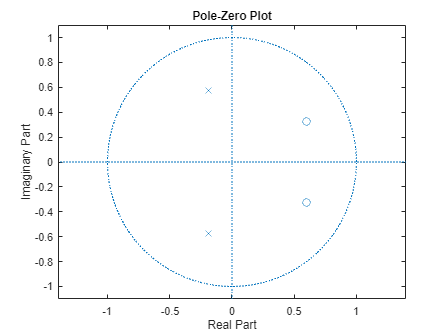

fs=1000;N=600;M=600;
fz1=80; z1=0.68*exp(-1j*2*pi*fz1/fs); z2=z1'; z=[z1,z2]';
fp1=300; p1=0.6*exp(-1j*2*pi*fp1/fs); p2=p1'; p=[p1,p2]';
figure;zplane(z,p)

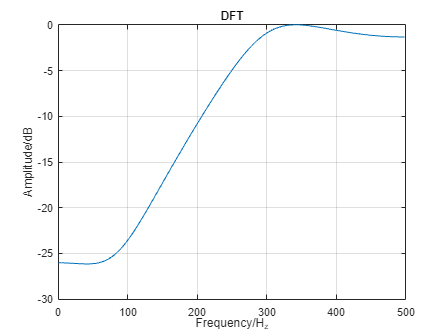

[b,a]=zp2tf(z,p,1);
[R,p,C]=residuez(b,a);
hn(1:M)=R(1)*(p(1).^(0:M-1))+R(2)*(p(2).^(0:M-1));
hn(1)=hn(1)+C(1);

x=impseq(0,0,600);
hn=filter(b,a,x);
[H,w]=freqz(b,a,N,'whole');
magH=abs(H);Hmax=max(magH);
figure;plot(w(1:N/2)*fs/2/pi,20*log10(magH(1:N/2)/Hmax)),title('DFT'),grid on ;
xlabel('Frequency/H_z'),ylabel('Amplitude/dB');

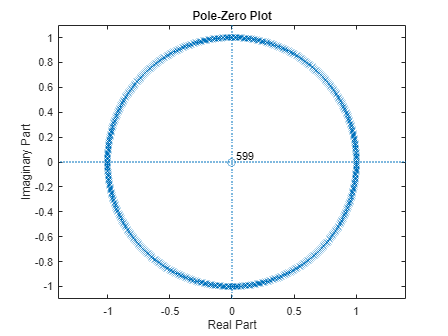

f2=400;f1=60;
W=1.0*exp(-1j*2*pi*(f2-f1)/(M*fs));
A=0.69*exp(1j*2*pi*f1/fs);
yz=czt(hn,M,W,A);
zk1=A*W.^(-(0:M-1));
figure;zplane(1,zk1)

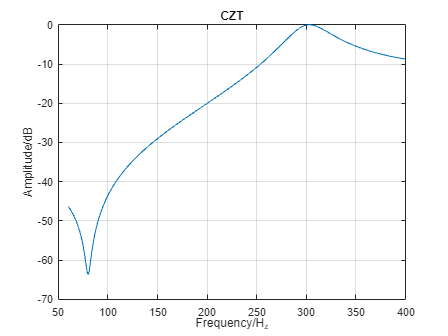

magyz=abs(yz);
yzmax=max(magyz);
wz=(0:M-1)*(f2-f1)/M+f1;
figure;plot(wz,20*log10(magyz/yzmax));title('CZT');grid;
xlabel('Frequency/H_z');
ylabel('Amplitude/dB');